clc;clear;close all;%基操
image_o=imread("15-刘德华.jpg");
image_o=im2double(image_o);

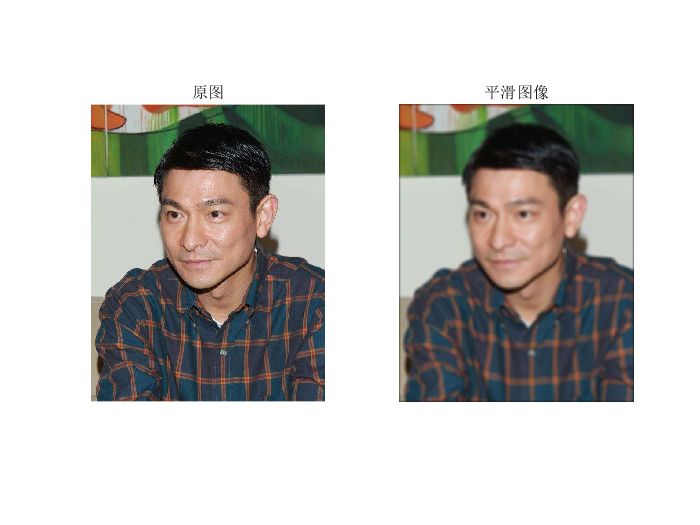

%对图像进行邻域平均法平滑处理，显示平滑前、后图像

num=9;%卷积核大小
core=ones(num,num)/num/num;
image_mean(:,:,1) = conv2(image_o(:,:,1),core,'same');%使用卷积均衡化，参数表卷积核大小
image_mean(:,:,2) = conv2(image_o(:,:,2),core,'same');
image_mean(:,:,3) = conv2(image_o(:,:,3),core,'same');

figure;
subplot(1,2,1);
imshow(image_o);
title("原图");
subplot(1,2,2);
imshow(image_mean);
title("平滑图像");

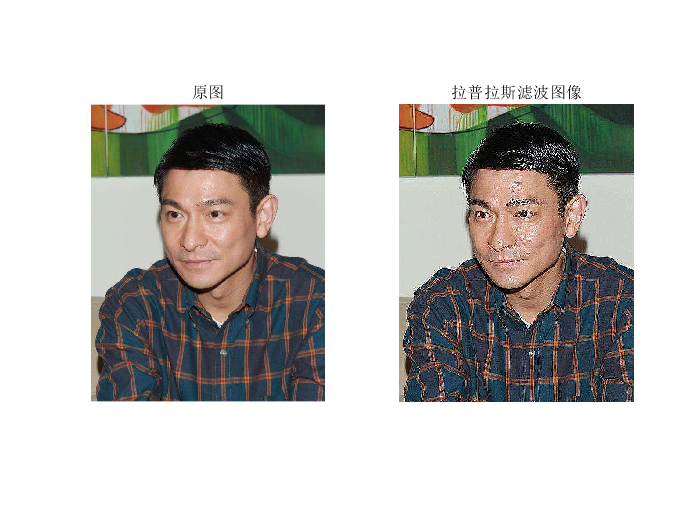

%对图像进行拉普拉斯锐化处理，显示锐化前、后图像

core=[-1,-1,-1;-1,8,-1;-1,-1,-1];%定义卷积核
image_lap(:,:,1) = conv2(image_o(:,:,1),core,'same');%使用卷积锐化，参数表卷积核大小
image_lap(:,:,2) = conv2(image_o(:,:,2),core,'same');
image_lap(:,:,3) = conv2(image_o(:,:,3),core,'same');
image_lap=image_lap/2+image_o;%将边缘与原图叠加，实现原图锐化

figure;
subplot(1,2,1);
imshow(image_o);
title("原图");
subplot(1,2,2);
imshow(image_lap);
title("拉普拉斯滤波图像");